
Single objective optimization:
2 Variable(s)

Options:
CreationFcn:       @gacreationlinearfeasible
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationpositivebasis

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100          -82.68          -6.718        0
    2              147          -143.3          -18.09        0
    3              194          -143.3          -21.07        1
    4              241          -143.3          -27.74        2
    5              288          -176.1          -40.48        0
    6              335          -176.1          -35.08        1
    7              382          -176.1          -56.03        2
    8              429          -176.1          -43.12        3
    9              476          -176.1          -34.27        4
   10              523          -176.1          -45.66        5
   1

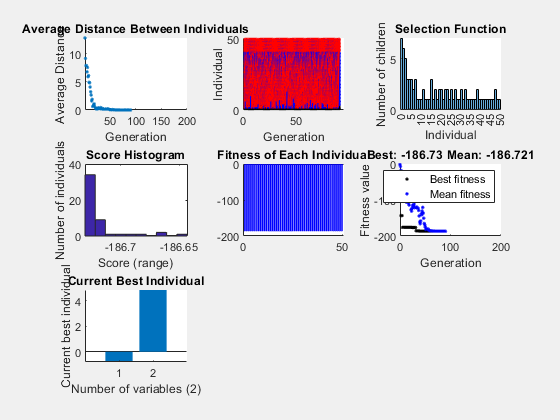

% Set nondefault solver options
options = optimoptions("ga","CreationFcn","gacreationlinearfeasible",...
    "MutationFcn","mutationpositivebasis","Display","iter","PlotFcn",...
    ["gaplotdistance","gaplotgenealogy","gaplotselection",...
    "gaplotscorediversity","gaplotscores","gaplotbestf","gaplotbestindiv"]);

% Solve
[solution,objectiveValue] = ga(fun,nvar,[],[],[],[],[],[],[],[],options);


% Clear variables
clearvars options

nvar = 2;
fun = @Shubert1_fun;
% Creation function 'gacreationlinearfeasible' and Mutation function
% 'mutationpositivebasis' gave best result so far, with -186.7304 at
% [-0.8008, 4.8581]. Global minima is -186.730909